clear; clc; close all;

% dB to the power
plexi_gain = 10; % [dB]
phan_gain = 35; % [dB]

load("BSC_measurements\acq_7Nov\plexy_baxX_E3.mat");

plexi = Cluster;
rf_plexi = plexi.RF_Data*10^((phan_gain-plexi_gain)/20);
tt_plexi = (0:length(rf_plexi)-1)/plexi.Fs;

sf = 2;
c = 1490;

trigger_th = 0.2;
max(abs(rf_plexi(:)))

ans = 17.7828

trigger_lim = round(max(abs(rf_plexi(:)))*1.5,1);
t0 = tt_plexi(find(abs(rf_plexi(1,:))>trigger_th, 1, 'first'))*1e6

t0 = 57.8400


inchtocm = 2.54;
sfcm = sf*inchtocm;
sftime = sfcm*1e-2*2/c*1e6 + t0;

wind = 2.8; %[us]

(wind*1e-6*c/2)*1e3 %[mm]

ans = 2.0860

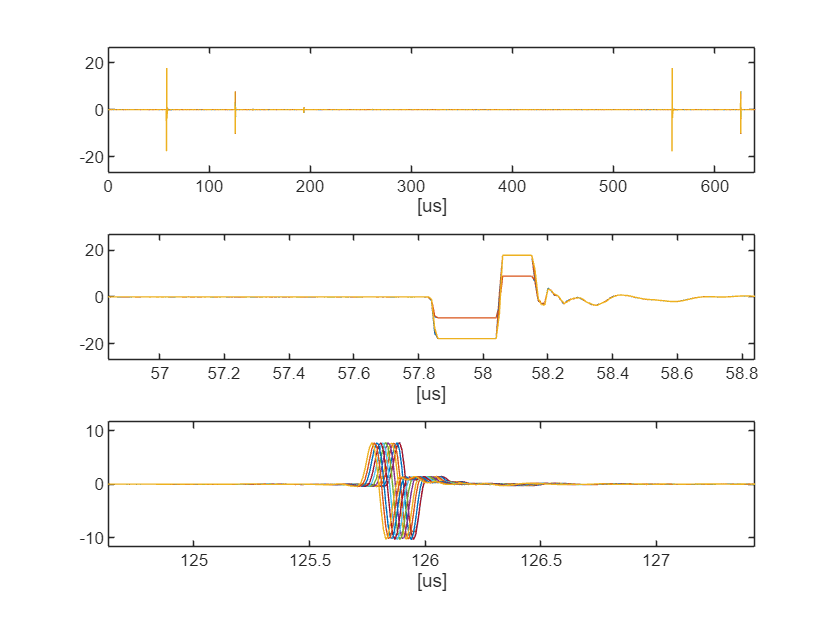


mask_plexi = (tt_plexi*1e6>(sftime-wind/2))&(tt_plexi*1e6<(sftime+wind/2));
wind_lim = round(max(rf_plexi(:,mask_plexi),[],'all')*1.5,1);

figure;
subplot(3,1,1)
plot(tt_plexi*1e6, rf_plexi(1:end,:));
xlabel('[us]'); xlim('tight');
ylim([-trigger_lim trigger_lim])

subplot(3,1,2)
plot(tt_plexi*1e6, rf_plexi(1:end,:));
xlabel('[us]'); xlim([t0-1 t0+1]);
ylim([-trigger_lim trigger_lim])

subplot(3,1,3)
plot(tt_plexi*1e6, rf_plexi(1:end,:));
xlabel('[us]'); xlim([sftime-wind/2 sftime+wind/2]);
ylim([-wind_lim wind_lim])

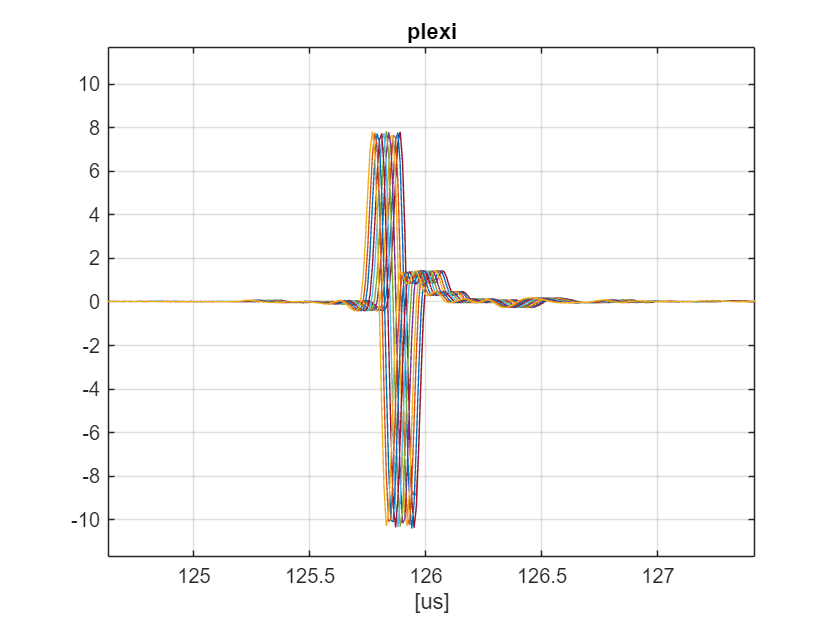



figure;
plot(tt_plexi(mask_plexi)*1e6, rf_plexi(:,mask_plexi));
xlabel('[us]'); title("plexi")
grid on; xlim('tight');
ylim([-wind_lim wind_lim])

load("BSC_measurements\acq_7Nov\phan_baxX_E3.mat");

phan = Cluster;
rf_phan = phan.RF_Data;
tt_phan = (0:length(rf_phan)-1)/phan.Fs;

sf = 2;
c = 1490;

trigger_th = 0.1;
max(abs(rf_phan(:)))

ans = 4.0258

trigger_lim = round(max(abs(rf_phan(:)))*1.5,1);
t0_ind = find(abs(rf_phan(1,:))>trigger_th, 1, 'first');
t0 = tt_phan(t0_ind)*1e6

t0 = 57.8400


inchtocm = 2.54;
sfcm = sf*inchtocm;
sftime = sfcm*1e-2*2/c*1e6 + t0; %150

sftime = 150


% wind = 2.5; %[mm]
mask_phan = (tt_phan*1e6>(sftime-wind/2))&(tt_phan*1e6<(sftime+wind/2));

PRF = 2e3;
[~,ind] = max(abs(rf_phan(1,round(t0_ind*1.5):(1/PRF*phan.Fs*0.8 + t0_ind))));
phan_start = tt_phan(ind+round(t0_ind*1.5))*1e6

phan_start = 124.1200

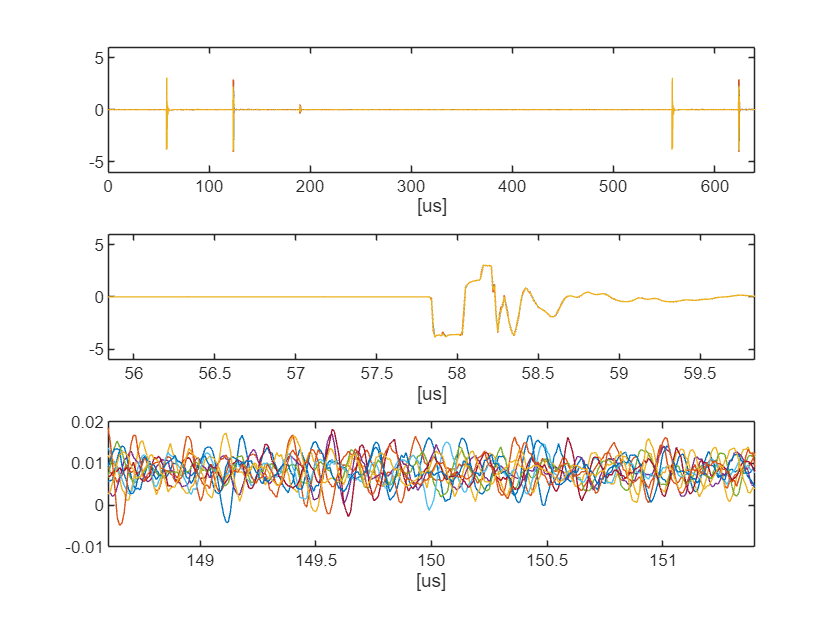



wind_lim = round(max(rf_phan(:,mask_phan),[],'all')*1.5, 2);

figure;
subplot(3,1,1)
plot(tt_phan*1e6, rf_phan(:,:));
xlabel('[us]'); xlim('tight');
ylim([-trigger_lim trigger_lim])

subplot(3,1,2)
plot(tt_phan*1e6, rf_phan(:,:));
xlabel('[us]'); xlim([t0-2 t0+2]);
ylim([-trigger_lim trigger_lim])

subplot(3,1,3)
plot(tt_phan*1e6, rf_phan(:,:));
xlabel('[us]'); xlim([sftime-wind/2 sftime+wind/2]);

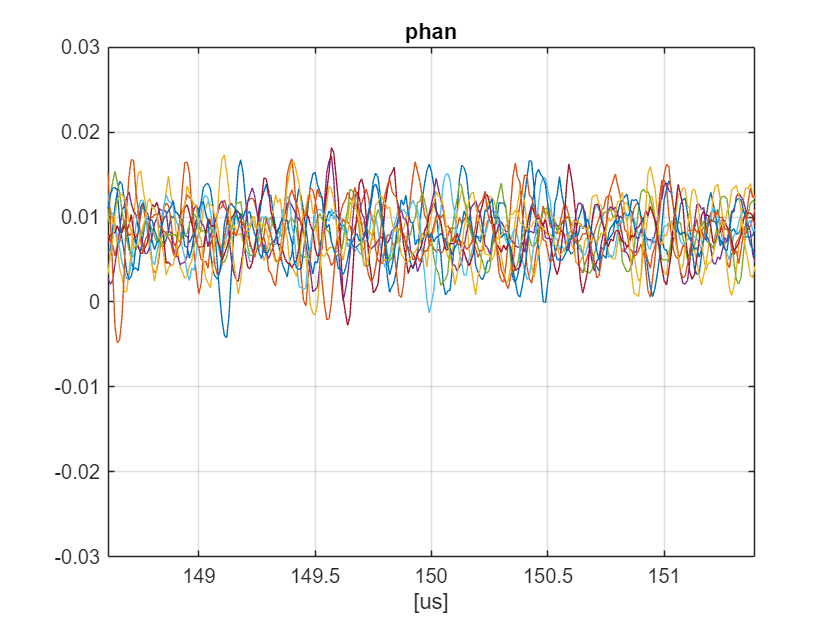

% ylim([-wind_lim wind_lim])

figure;
plot(tt_phan(mask_phan)*1e6, rf_phan(:,mask_phan));
xlabel('[us]'); title("phan")
grid on; xlim('tight');
ylim([-wind_lim wind_lim])

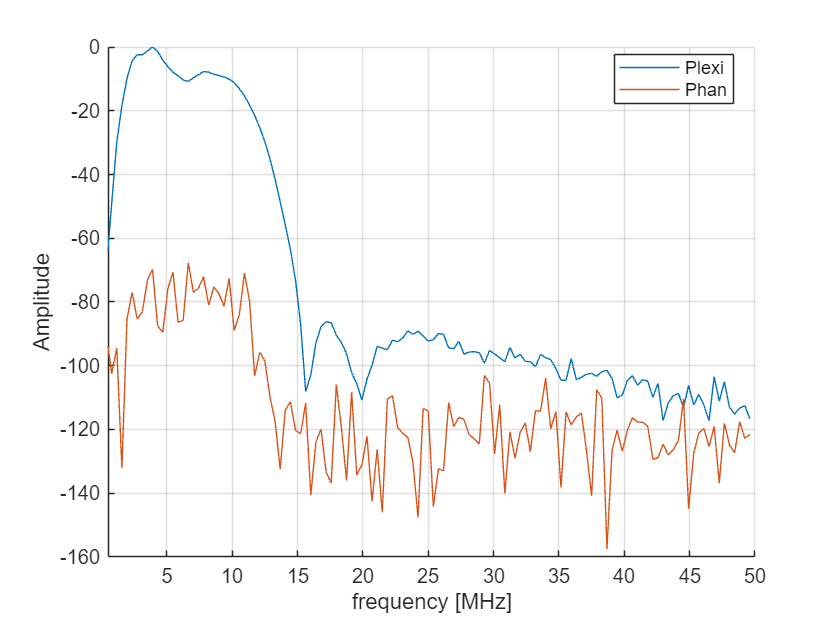

NFFT = 2^8;
y_plexi = mean(fftshift(fft(rf_plexi(:,mask_plexi),NFFT,2)),1);
y_phan = mean(fftshift(fft(rf_phan(:,mask_phan),NFFT,2)),1);

freq = (0:length(y_plexi)-1)*plexi.Fs/length(y_plexi) - plexi.Fs/2;
freq_phan = (0:length(y_phan)-1)*phan.Fs/length(y_phan) - phan.Fs/2;

y_pow_plexi = abs(y_plexi).^2;
y_pow_phan = abs(y_phan).^2;

figure;
hold on
plot(freq*1e-6, db(y_pow_plexi/max(y_pow_plexi)));
plot(freq_phan*1e-6, db(y_pow_phan/max(y_pow_phan))); hold off
ylabel("Amplitude"); xlabel("frequency [MHz]"); grid on;
legend("Plexi","Phan", 'Location','best')
xlim([0.5 50])


c0_agua = 1490;
c0_phantom = 1540;

BW = [1.5 12];
mask_f= (freq>=BW(1)*1e6 & freq<BW(2)*1e6);

% Define standard values for the parameters
gamma = 0.37 % Reflection coefficient, depending on the reflector material

gamma = 0.3700

F = sf*2.54 % Focal distance in cm

F = 5.0800

R = (0.5*2.54/2) % Radius of the transducer in cm

R = 0.6350

Delta_z = (wind*1e-6*c/2)*1e2 % Axial length in cm

Delta_z = 0.2086

Gp = (2*pi*freq(mask_f)/c0_agua)*(R*1e-2)^2/(2*(F*1e-2)); % All in SI
% Geometry parameter, typically related to the aperture and wavelength


delta_att = ((sftime+wind/2-phan_start)*1e-6*c/2)*1e2

delta_att = 2.0324

alpha_phan = 0.50*log(10)/20 %/8.868; Np/cm/MHz

alpha_phan = 0.0576

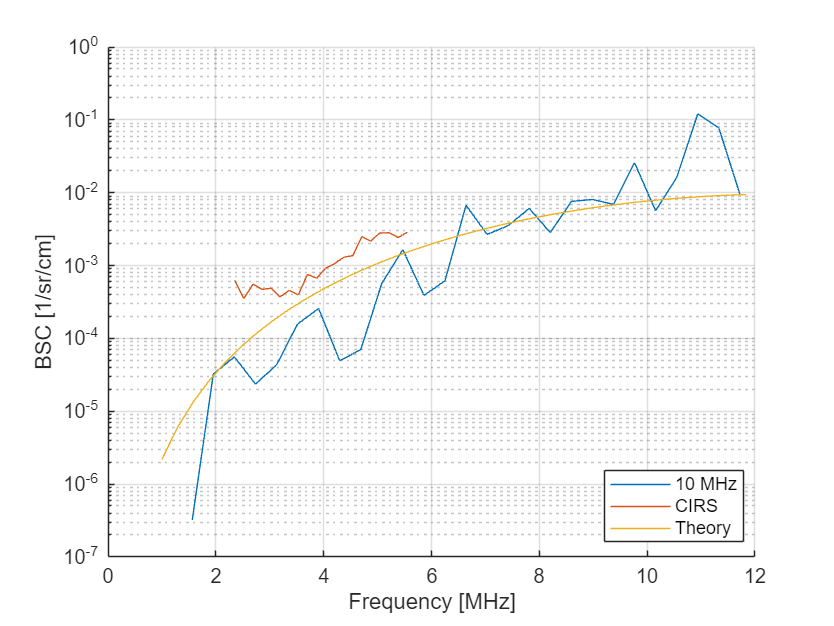

A_omega_f_F = exp(-4*alpha_phan*freq(mask_f)*1e-6*(delta_att));

%((1-exp(-alpha_phan*freq(mask_f)*1e-6*delta_att))./(alpha_phan*freq(mask_f)*1e-6*delta_att)); % Attenuation compensation factor

% figure;
% subplot(2,1,1)
% plot(freq(mask_f)*1e-6, Gp); title("Geometry parameter")
% subplot(2,1,2)
% plot(freq(mask_f)*1e-6, A_omega_f_F); title("Attenuation")

% Define the Bessel functions as they are used in the D function
J0 = besselj(0, Gp);
J1 = besselj(1, Gp);

% Calculate D(Gp)
D_Gp = abs(exp(-1j*Gp).*(J0 + 1j*J1) - 1).^2;

% Define S(omega_f, F) as needed, here we use a placeholder value
S_omega_f_F = y_pow_phan(mask_f); % This would be measured or calculated based on your system
Sw_f = y_pow_plexi(mask_f);

% Calculate BSC using the equation
sigma_f = (2.17.* D_Gp * gamma^2 * F^2 .*S_omega_f_F)./ ...
    (A_omega_f_F.*pi * R^2 * Delta_z.* Sw_f.*(transmission_membrane(freq(mask_f)*1e-6)));

BSC_theory_liver = load("mpUS_rats_2022\duke_bsc\BSC_liver_theory.mat");
BSC_theory_liver = BSC_theory_liver.bsc_liver;
freq_liver_theory = load("mpUS_rats_2022\duke_bsc\BSC_freq_theory.mat");
freq_liver_theory = freq_liver_theory.freqs_liver;

BSC_CIRS_liver = readmatrix("mpUS_rats_2022\Phantom_characterization\2096-00 Full acoustic characterization data.xlsx", ...
    "Range", "A2:B21","Sheet",2);

% Display the result
figure;
hold on
plot(freq(mask_f)*1e-6, sigma_f);
plot(BSC_CIRS_liver(:,1), BSC_CIRS_liver(:,2));
plot(freq_liver_theory(freq_liver_theory<BW(2)), BSC_theory_liver(freq_liver_theory<BW(2)));
hold off
xlabel("Frequency [MHz]"); grid on; ylabel("BSC [1/sr/cm]")
legend("10 MHz","CIRS","Theory",'Location','best')
xlim([0 BW(2)]);
set(gca, "YScale",'log')

trans = transmission_membrane(freq(mask_f)*1e-6);
transaran = transmission_saran(freq(mask_f)*1e-6);

function t = transmission_membrane(band)
a = -0.087146134643529;
b = 0.642790369805658;
c = 1.052562238394482;
t = (a*band.^(b)+c).^4;
end

function t=transmission_saran(band)
c_s = 2400; %[m/s]
c_p = 1540; %[m/s]
rho_s = 1690; %[kg/m^3]
rho_p = 1000; %[kg/m^3]
Z_p = c_p*rho_p;
Z_s = c_s*rho_s;

f0 = band*1e6;  %[Hz]
alpha = 5*(band).^1.5; %[Np/MHz^1.5/m]
L = 25.1e-6; %[m]


t = abs(     2*Z_p ./...
    (    (2*Z_p)*cos((2*pi*f0/c_s - 1i*alpha)*L) ...
    + 1i *(Z_s+Z_p^2/Z_s)*sin((2*pi*f0/c_s - 1i*alpha)*L) )) .^4;

end